# КУМС. ЛР №2

**Параметрический синтез и исследование цифровой системы управления с П-регулятором и объектом в виде последовательно включенных апериодического и интегрирующего звеньев из условия обеспечения заданного переходного процесса.**

Денис Кирбаба, R3438

### 1. Параметры по вариантам

% ob.R = 1 + unifrnd(-0.3,0.3);  % сопротивление обмоток двигателя
% ob.L = 0.06 + unifrnd(-0.01,0.01);  % индуктивность обмоток двигателя
% ob.J = 150 + unifrnd(-10,10);  % момент инерции
% ob.Ce = 2;  % константа противо-ЭДС
% ob.Cm = ob.Ce;  % константа по моменту
% ob.kdw = 180/pi;  % коэффициент передачи датчика скорости (пересчет из радиан в градусы)
% save('data.mat','ob')

load("data.mat")

Установившееся значение скорости холостого хода: n_0 = 1/ob.Ce*ob.kdw

1/ob.Ce*ob.kdw

ans = 28.6479

### 2. Моделирование цифрового П-регулятора

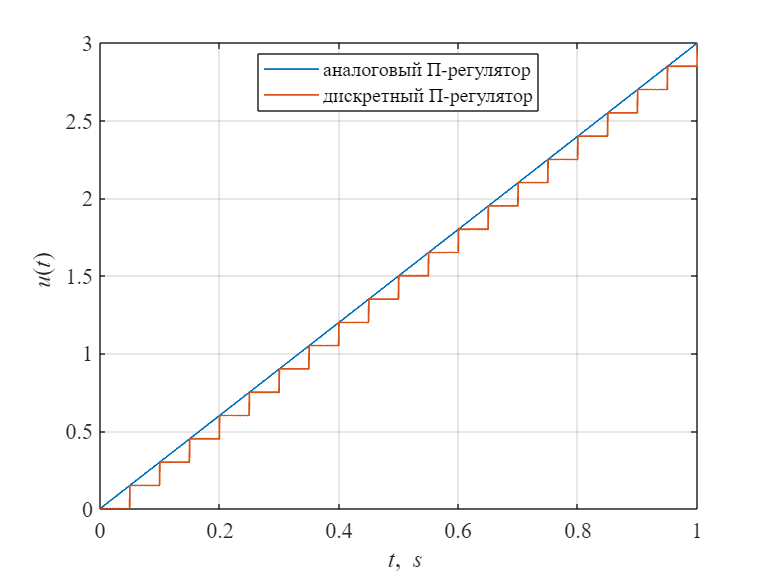

an.Kp = 3;
dsc.Kp = an.Kp;

Tmdl = 1;
To = 0.05;

warning off
SimNew = sim('lab2p2.slx','ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.y(:,1);
an.y = SimNew.y(:,2);
dsc.y = SimNew.y(:,3);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,an.y,'LineWidth',1)
hold on
grid on
plot(t,dsc.y,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it u\rm(\itt\rm)')
legend('аналоговый П-регулятор','дискретный П-регулятор','Location','best')

2.1. Графики работы аналогового и дискретного П-регуляторов.

Цифровая система немного запаздывает от аналоговой даже в таком просто случае. Засчет ЦАПа она обладает запаздыванием. Можно уменьшить шумы дискретизации за счет линейно экстраполятора (экстраполятора 1 порядка), однако в таком случае запаздывание будет больше так как необходимо будет знать следующее значение сигнала для линейной экстраполяции.

Настроим контур тока на линейный оптимум с помощью аналогово регулятора.

Контур тока будет аналоговым, а контур скорости дискретным. Для того чтобы у нас получился объект в виде последовательно соединенного интегрального звена и апериодического.    

### 3. Синтез системы управления с использованием "метода переоборудования"

#### (a) Синтез аналогового регулятора контура тока

syms ia ua Md wd ea  % ток, напряжение, момент, скорость, противо-ЭДС
syms L R J Ce  % индуктивность, сопротивление, момент инерции, коэффициент противо-ЭДС
syms dia dwd  % производные по току и по скорости

eq(1) = ua - ea == L*dia + R*ia;  % уравнение для электрической части
eq(2) = J*dwd == Md;  % уравнение для механической части
eq(3) = Md == Ce*ia;
eq(4) = ea == Ce*wd;

S = solve(eq,[dia dwd Md ea]);
disp(collect(S.dia,[ia wd ua]))

$$\left(-\frac{R}{L}\right)\,\mathrm{ia}+\left(-\frac{\mathrm{Ce}}{L}\right)\,\mathrm{wd}+\frac{\mathrm{ua}}{L}$$

disp(collect(S.dwd,[ia wd ua]))

$$\frac{\mathrm{Ce}}{J}\,\mathrm{ia}$$

A = [-R/L -Ce/L;
     Ce/J 0];
B = [1/L; 0];
C = [1 0];
D = 0;

syms s
crl.Wob = C*(s*eye(2)-A)^-1*B+D;
disp(collect(crl.Wob))

$$\frac{J\,s}{\left(J\,L\right)\,s^{2}+\left(J\,R\right)\,s+{\mathrm{Ce}}^{2}}$$

% такое упрощение можно делать только в случае, если J большое
crl.Wob_smpl = 1/(L*s+R);
disp(collect(crl.Wob_smpl))

$$\frac{1}{L\,s+R}$$

#### Сравнение частотных характеристик реальной и упрощенной моделей

По сути, частотная характеристика это отношение спектра сигнала на выходе к спектру сигнала на входе. Спектр это преобразование Фурье от сигнала, то есть его разбиение на определенные гармоники.

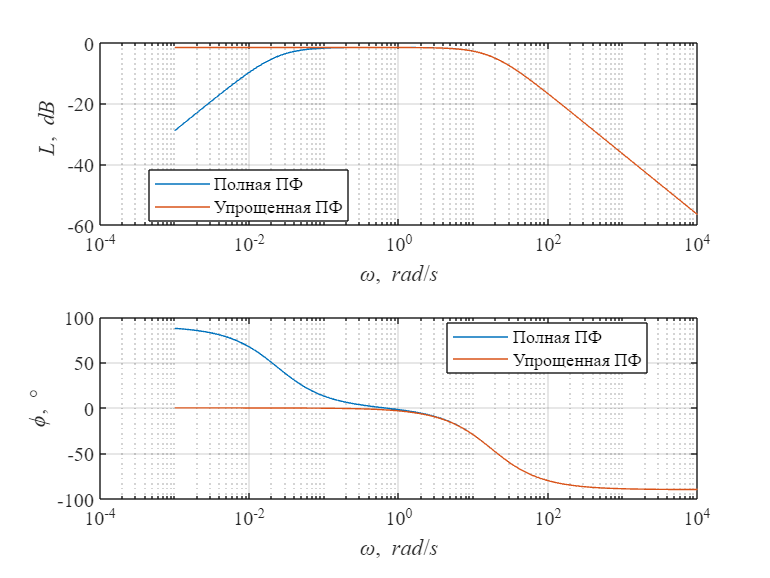

wfr = 10.^(-3:0.01:4);
sfr = 1i*wfr;

Hw = ob.J*sfr./(ob.J*ob.L*sfr.^2+ob.J*ob.R*sfr+ob.Ce^2);
Hw_smpl = 1./(ob.L*sfr+ob.R);

Lw = 20*log10(abs(Hw));
Lw_smpl = 20*log10(abs(Hw_smpl));

phi = angle(Hw);
phi_smpl = angle(Hw_smpl);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(wfr,Lw)
hold on
grid on
plot(wfr,Lw_smpl)
set(ax(1),'XScale','log')
xlabel('\omega\rm,\it rad\rm/\its')
ylabel('\it L\rm, \itdB')
legend('Полная ПФ','Упрощенная ПФ','Location','best')

ax(2) = subplot(2,1,2);
plot(wfr,phi*180/pi)
hold on
grid on
plot(wfr,phi_smpl*180/pi)
set(ax(2),'XScale','log')
xlabel('\omega\rm,\it rad\rm/\its')
ylabel('\phi\rm, \circ')
legend('Полная ПФ','Упрощенная ПФ','Location','best')

linkaxes(ax,'x')

В облатси высоких частот частотные характеристики совпадают, а в области низких частот они расходятся. Соответственно, если мы будем настраивать регулятор с полосой пропускания в области высоких частот, то расхождение на низких частотах не будет влиять и в такой ситуации можно заменить полную модель на упрощенную.

Если мы настраиваем регулятор в области низких частот (то есть медленный), то у нас будут сильные различия между системами.

#### Расчет ПИ регулятора тока

Для синтеза регулятора использовали упрощенную модель, но синтезируемый регулятор будем использовать на полной модели.

syms Tt s
crl.Wol = 1/(Tt*s);
crl.Wreg = crl.Wol/crl.Wob_smpl;

disp(collect(crl.Wreg,s))

$$\frac{L\,s+R}{\mathrm{Tt}\,s}$$

#### Анализ области применения упрощенной ПФ при синтезе контура тока

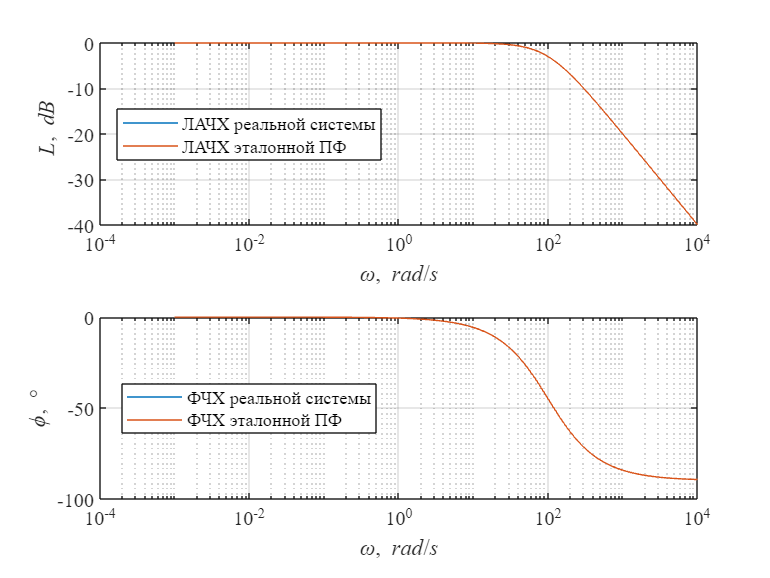

crl.Tt = 0.01;
crl.Kp = ob.L/crl.Tt;
crl.Ki = ob.R/crl.Tt;

crl.Wreg_w = (ob.L*sfr+ob.R)./(crl.Tt*sfr);

crl.Wcl_w = crl.Wreg_w.*Hw./(1+crl.Wreg_w.*Hw);
crl.Wet = 1./(crl.Tt*sfr+1);

Lw = 20*log10(abs(crl.Wcl_w));
Lw_et = 20*log10(abs(crl.Wet));

phi = angle(crl.Wcl_w);
phi_et = angle(crl.Wet);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(wfr,Lw)
hold on
grid on
plot(wfr,Lw_et)
set(ax(1),'XScale','log')
xlabel('\omega\rm,\it rad\rm/\its')
ylabel('\it L\rm, \itdB')
legend('ЛАЧХ реальной системы','ЛАЧХ эталонной ПФ','Location','best')

ax(2) = subplot(2,1,2);
plot(wfr,phi*180/pi)
hold on
grid on
plot(wfr,phi_et*180/pi)
set(ax(2),'XScale','log')
xlabel('\omega\rm,\it rad\rm/\its')
ylabel('\phi\rm, \circ')
legend('ФЧХ реальной системы','ФЧХ эталонной ПФ','Location','best')

linkaxes(ax,'x')

#### Моделирование работы контура тока

Tmdl = 0.1;
To = 0.05;

warning off
SimNew = sim('lab2p3.slx','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
lab2p3/crl.Kp
lab2p3/Sum
lab2p3/Electric Drive/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2p3/Electric Drive/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2p3/Sum1 (algebraic variable)


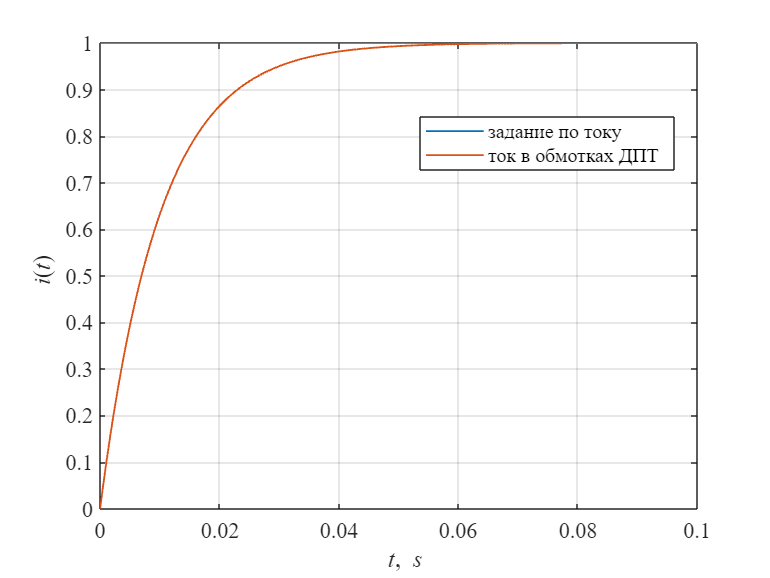

warning on

t = SimNew.y(:,1);
i_ref=SimNew.y(:,2);
i_sens=SimNew.y(:,3);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,i_ref,'LineWidth',1)
hold on
grid on
plot(t,i_sens,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it i\rm(\itt\rm)')
legend('задание по току','ток в обмотках ДПТ','Location','best')

syms Tu s Tt kwd

crl.Wcl = crl.Wol/(1+crl.Wol);
disp(collect(crl.Wcl,s))

$$\frac{1}{\mathrm{Tt}\,s+1}$$

spl.Wob = crl.Wcl*Ce*kwd/(J*s);
spl.Wol = 1/(3*Tu*s*(Tu*s+1));
spl.Wreg = spl.Wol/spl.Wob;
disp(collect(spl.Wreg))

$$\frac{\left(J\,\mathrm{Tt}\right)\,s+J}{\left(3\,\mathrm{Ce}\,{\mathrm{Tu}}^{2}\,\mathrm{kwd}\right)\,s+3\,\mathrm{Ce}\,\mathrm{Tu}\,\mathrm{kwd}}$$

Получился ПИ-регулятор с запаздыванием. Но этот регулятор мы будем использовать при условии что с помощью такого регулятора мы будем компенсировать все постоянные времени. Если же мы не компенсируем все постоянные времени, а они у нас всегда есть (это малые постоянные времени, которыми пренебрегать нельзя, которые компенсировать нельзя, это запаздывание датчика скорости или тока, постоянная времени преобразователя). В данной ситуации мы не будем компенсировать постоянную времени контура тока, поэтому положим Tu=Tt.

syms Tu s Tt

crl.Wcl = crl.Wol/(1+crl.Wol);
disp(collect(crl.Wcl,s))

$$\frac{1}{\mathrm{Tt}\,s+1}$$

spl.Wob = crl.Wcl*Ce*kwd/(J*s);
Tu = Tt;
spl.Wol = 1/(3*Tu*s*(Tu*s+1));
spl.Wreg = spl.Wol/spl.Wob;
disp(collect(spl.Wreg))

$$\frac{J}{3\,\mathrm{Ce}\,\mathrm{Tt}\,\mathrm{kwd}}$$

Итого, получили что требуемый регулятор это П-регулятор. Только вместо Tt в регуляторе будет Tu.

#### (c) Моделирование работы системы настроенной на биномиальный оптимум

crl.Tt = 0.05;
crl.Kp = ob.L/crl.Tt;
crl.Ki = ob.R/crl.Tt;

spl.Tu = crl.Tt;
spl.Kp = ob.J/(3*ob.Ce*spl.Tu*ob.kdw);
spl.Kpd = spl.Kp;

Tmdl = 0.6;

To = 0.1Tt

To = 0.1*crl.Tt;

warning off
SimNew = sim('lab2p3c.slx','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
lab2p3c/Subsystem/crl.Kp
lab2p3c/Subsystem/Sum
lab2p3c/Electric Drive/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2p3c/Electric Drive/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2p3c/Subsystem/Sum1 (algebraic variable)
Found algebraic loop containing: 
lab2p3c/Subsystem1/crl.Kp
lab2p3c/Subsy

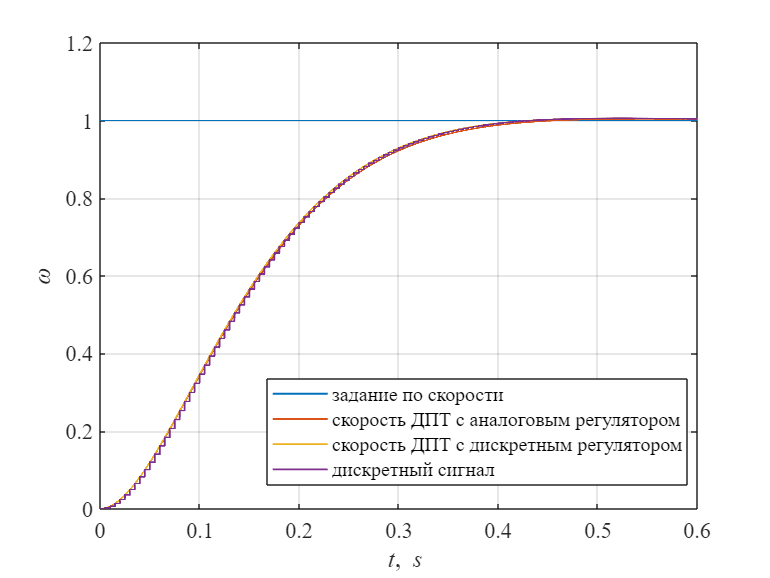

warning on

t = SimNew.w(:,1);
wref=SimNew.w(:,2);
wa=SimNew.w(:,3);
wd=SimNew.w(:,4);
wdg=SimNew.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'LineWidth',1)
hold on
grid on
plot(t,wa,'LineWidth',1)
plot(t,wd,'LineWidth',1)
plot(t,wdg,'LineWidth',1)
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\omega')
legend('задание по скорости','скорость ДПТ с аналоговым регулятором','скорость ДПТ с дискретным регулятором','дискретный сигнал','Location','best')

Видим, что графики переходных процессов особо не отличаются. То есть в данном случае, когда To=0.1Tt никаких дополнительных действий не требуется. Можно расчитывать пропорциональный регулятор также как у нас был расчитан аналоговый регулятор.

Рассчитаем показатели качества переходного процесса ДПТ с дискретным регулятором

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp1 для 5% зоны: 6.5*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp2 для 5% зоны: 6.5*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 0.1%


За счет того, что перерегулирование оказалось чуть больше 5%, переходный процесс заканчивается в 6.3Tu так как мы выходим из 5% зоны.

Tmdl = 0.8;

To = Tt

To = crl.Tt;

warning off
SimNew = sim('lab2p3c.slx','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
lab2p3c/Subsystem/crl.Kp
lab2p3c/Subsystem/Sum
lab2p3c/Electric Drive/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2p3c/Electric Drive/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2p3c/Subsystem/Sum1 (algebraic variable)
Found algebraic loop containing: 
lab2p3c/Subsystem1/crl.Kp
lab2p3c/Subsy

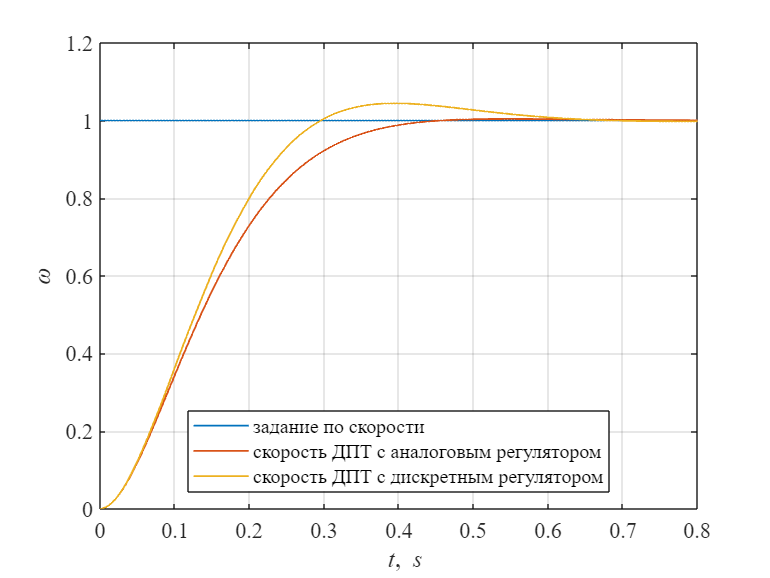

warning on

t = SimNew.w(:,1);
wref=SimNew.w(:,2);
wa=SimNew.w(:,3);
wd=SimNew.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'LineWidth',1)
hold on
grid on
plot(t,wa,'LineWidth',1)
plot(t,wd,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\omega')
legend('задание по скорости','скорость ДПТ с аналоговым регулятором','скорость ДПТ с дискретным регулятором','Location','best')

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp1 для 5% зоны: 5.2*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp2 для 5% зоны: 5.2*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 4.6%


To = spl.Tu;

for i = 1:10
    spl.Tz = i/10*To;  % диапазон изменения Tz
    Tzap(i) = spl.Tz;
    warning off
    SimNew = sim('lab2p4.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = SimNew.w(:,1);
    wa = SimNew.w(:,3);
    wd = SimNew.w(:,4);
    f(i) = trapz(t,abs(wd-wa));  % интеграл разности между переходными функциями, рассчитанный по методу трапеции
end

Found algebraic loop containing: 
lab2p4/Subsystem/crl.Kp
lab2p4/Subsystem/Sum
lab2p4/Electric Drive/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2p4/Electric Drive/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2p4/Subsystem/Sum1 (algebraic variable)
Found algebraic loop containing: 
lab2p4/Subsystem1/crl.Kp
lab2p4/Subsystem1/Sum


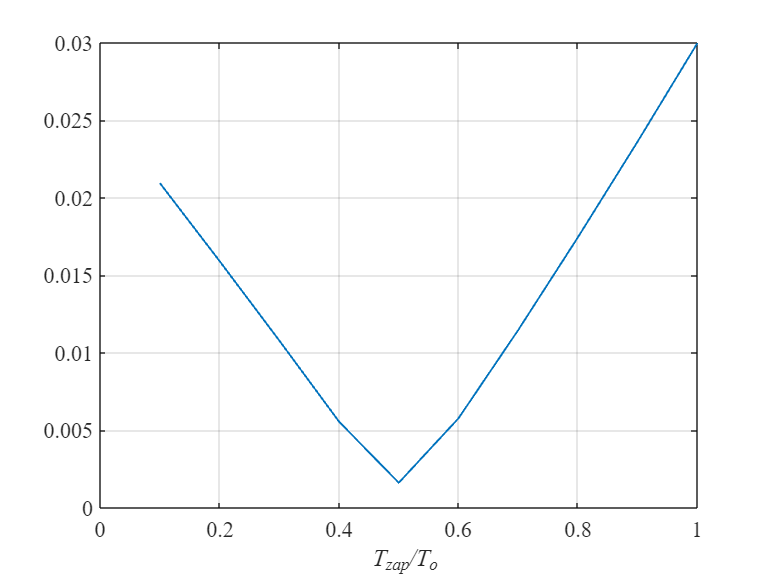

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')

crl.Tt = 0.05;
To = crl.Tt;

crl.Kp = ob.L/crl.Tt;
crl.Ki = ob.R/crl.Tt;

spl.Tz = 0.5*To;
spl.Tu = crl.Tt + spl.Tz;
spl.Kp = ob.J/(3*ob.Ce*spl.Tu*ob.kdw);
spl.Kpd = spl.Kp;

Tmdl = 0.8;

warning off
SimNew = sim('lab2p4.slx','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
lab2p4/Subsystem/crl.Kp
lab2p4/Subsystem/Sum
lab2p4/Electric Drive/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2p4/Electric Drive/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2p4/Subsystem/Sum1 (algebraic variable)
Found algebraic loop containing: 
lab2p4/Subsystem1/crl.Kp
lab2p4/Subsystem1/Sum


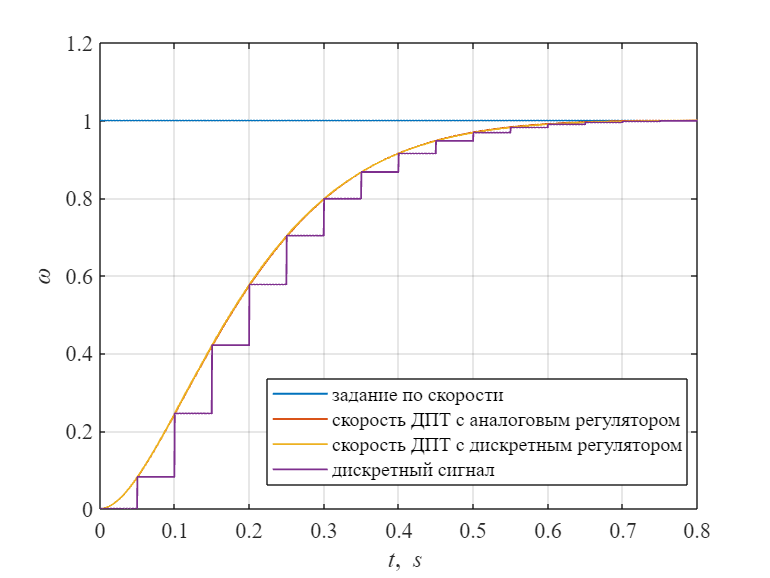

warning on

t = SimNew.w(:,1);
wref=SimNew.w(:,2);
wa=SimNew.w(:,3);
wd=SimNew.w(:,4);
wdg=SimNew.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'LineWidth',1)
hold on
grid on
plot(t,wa,'LineWidth',1)
plot(t,wd,'LineWidth',1)
plot(t,wdg,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\omega')
legend('задание по скорости','скорость ДПТ с аналоговым регулятором','скорость ДПТ с дискретным регулятором','дискретный сигнал','Location','best')

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp1 для 5% зоны: 6.1*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp2 для 5% зоны: 6.1*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 0.0%


crl.Tt = 0.05;
To = 2*crl.Tt;

crl.Kp = ob.L/crl.Tt;
crl.Ki = ob.R/crl.Tt;

spl.Tz = 0.5*To;
spl.Tu = crl.Tt + spl.Tz;
spl.Kp = ob.J/(3*ob.Ce*spl.Tu*ob.kdw);
spl.Kpd = spl.Kp;

Tmdl = 1.2;

warning off
SimNew = sim('lab2p4.slx','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
lab2p4/Subsystem/crl.Kp
lab2p4/Subsystem/Sum
lab2p4/Electric Drive/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2p4/Electric Drive/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2p4/Subsystem/Sum1 (algebraic variable)
Found algebraic loop containing: 
lab2p4/Subsystem1/crl.Kp
lab2p4/Subsystem1/Sum


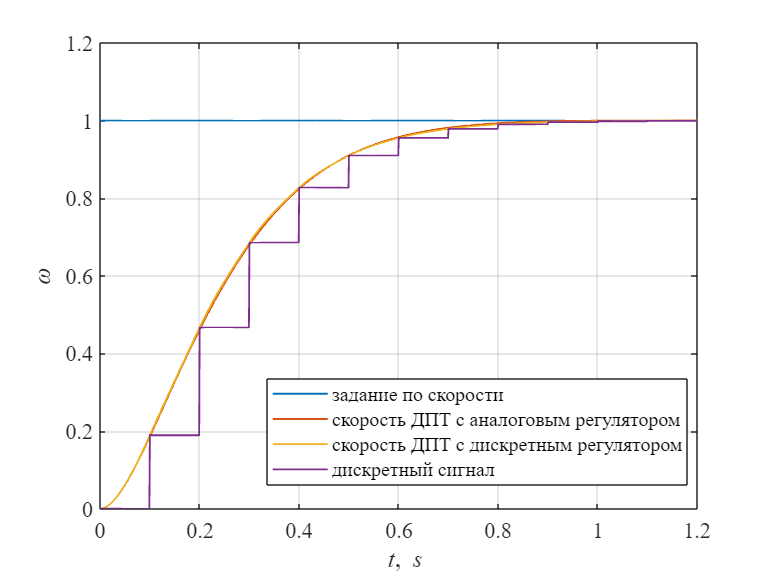

warning on

t = SimNew.w(:,1);
wref=SimNew.w(:,2);
wa=SimNew.w(:,3);
wd=SimNew.w(:,4);
wdg=SimNew.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'LineWidth',1)
hold on
grid on
plot(t,wa,'LineWidth',1)
plot(t,wd,'LineWidth',1)
plot(t,wdg,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\omega')
legend('задание по скорости','скорость ДПТ с аналоговым регулятором','скорость ДПТ с дискретным регулятором','дискретный сигнал','Location','best')

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp1 для 5% зоны: 5.8*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp2 для 5% зоны: 5.8*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 0.0%


To = spl.Tu;
Tmdl = 1.5;

for i = 1:20
    spl.Tz = i/10*To;  % диапазон изменения Tz
    Tzap(i) = spl.Tz;
    warning off
    SimNew = sim('lab2p5.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = SimNew.w(:,1);
    wa = SimNew.w(:,3);
    wd = SimNew.w(:,4);
    f(i) = trapz(t,abs(wd-wa));  % интеграл разности между переходными функциями, рассчитанный по методу трапеции
end

Found algebraic loop containing: 
lab2p5/Subsystem/crl.Kp
lab2p5/Subsystem/Sum
lab2p5/Electric Drive/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2p5/Electric Drive/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2p5/Subsystem/Sum1 (algebraic variable)
Found algebraic loop containing: 
lab2p5/Subsystem1/crl.Kp
lab2p5/Subsystem1/Sum


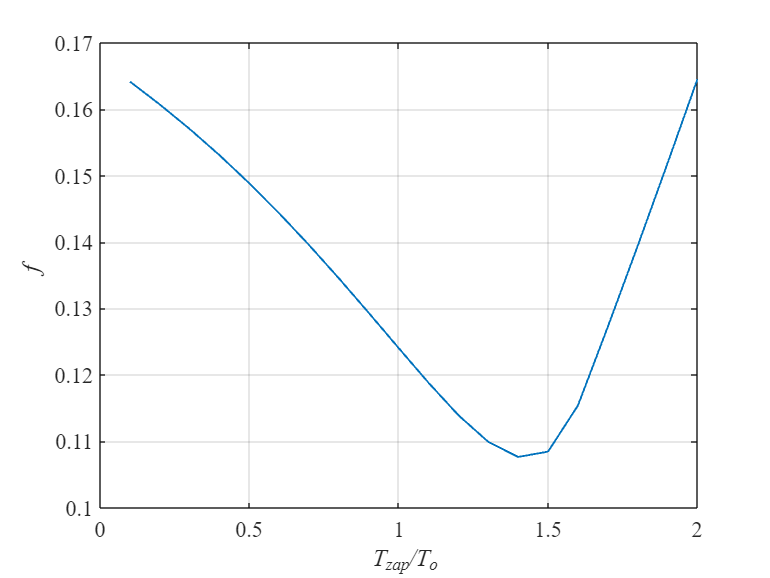

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

crl.Tt = 0.05;
To = crl.Tt;

crl.Kp = ob.L/crl.Tt;
crl.Ki = ob.R/crl.Tt;

spl.Tz = 1.4*To;
spl.Tu = crl.Tt + spl.Tz;
spl.Kp = ob.J/(3*ob.Ce*spl.Tu*ob.kdw);
spl.Kpd = spl.Kp;

Tmdl = 1.2;

warning off
SimNew = sim('lab2p5.slx','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
lab2p5/Subsystem/crl.Kp
lab2p5/Subsystem/Sum
lab2p5/Electric Drive/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2p5/Electric Drive/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2p5/Subsystem/Sum1 (algebraic variable)
Found algebraic loop containing: 
lab2p5/Subsystem1/crl.Kp
lab2p5/Subsystem1/Sum


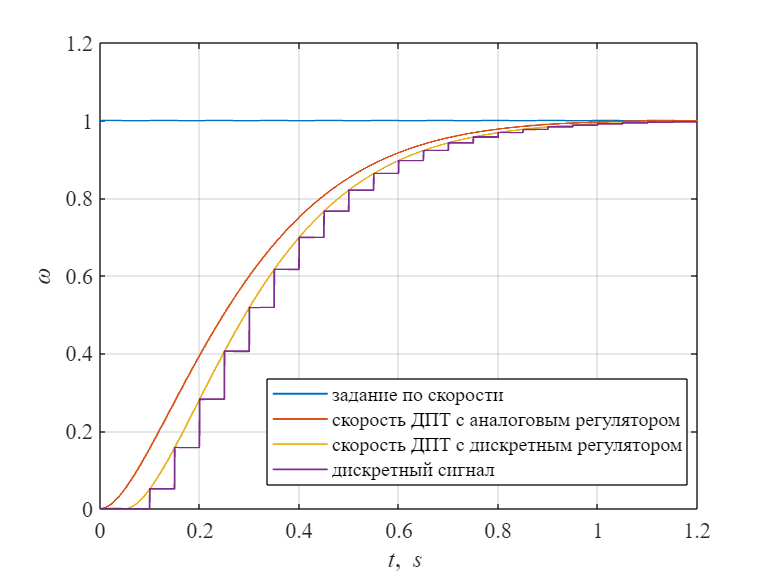

warning on

t = SimNew.w(:,1);
wref=SimNew.w(:,2);
wa=SimNew.w(:,3);
wd=SimNew.w(:,4);
wdg=SimNew.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'LineWidth',1)
hold on
grid on
plot(t,wa,'LineWidth',1)
plot(t,wd,'LineWidth',1)
plot(t,wdg,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\omega')
legend('задание по скорости','скорость ДПТ с аналоговым регулятором','скорость ДПТ с дискретным регулятором','дискретный сигнал','Location','best')

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp1 для 5% зоны: 6.0*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp2 для 5% зоны: 6.0*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 0.0%


crl.Tt = 0.05;
To = 2*crl.Tt;

crl.Kp = ob.L/crl.Tt;
crl.Ki = ob.R/crl.Tt;

spl.Tz = 1.4*To;
spl.Tu = crl.Tt + spl.Tz;
spl.Kp = ob.J/(3*ob.Ce*spl.Tu*ob.kdw);
spl.Kpd = spl.Kp;

Tmdl = 1.8;

warning off
SimNew = sim('lab2p5.slx','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
lab2p5/Subsystem/crl.Kp
lab2p5/Subsystem/Sum
lab2p5/Electric Drive/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2p5/Electric Drive/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2p5/Subsystem/Sum1 (algebraic variable)
Found algebraic loop containing: 
lab2p5/Subsystem1/crl.Kp
lab2p5/Subsystem1/Sum


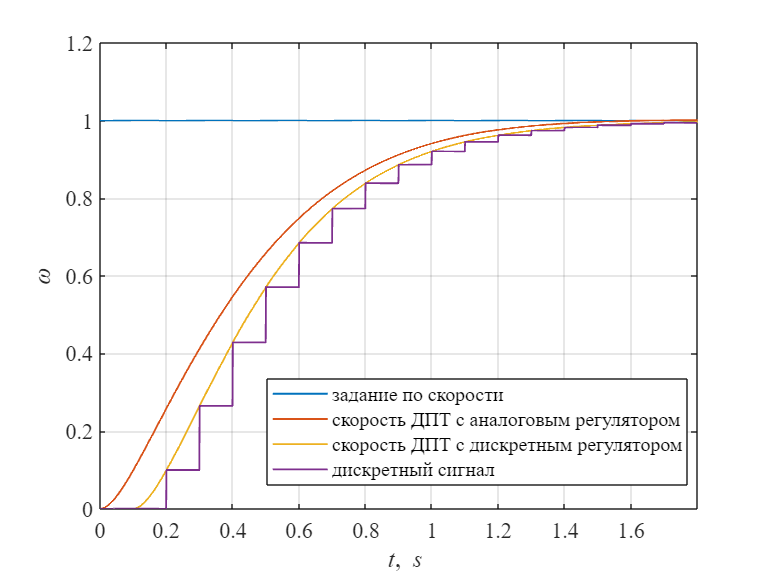

warning on

t = SimNew.w(:,1);
wref=SimNew.w(:,2);
wa=SimNew.w(:,3);
wd=SimNew.w(:,4);
wdg=SimNew.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'LineWidth',1)
hold on
grid on
plot(t,wa,'LineWidth',1)
plot(t,wd,'LineWidth',1)
plot(t,wdg,'LineWidth',1)
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\omega')
legend('задание по скорости','скорость ДПТ с аналоговым регулятором','скорость ДПТ с дискретным регулятором','дискретный сигнал','Location','best')

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp1 для 5% зоны: 5.8*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp2 для 5% зоны: 5.8*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 0.0%
